快速OIR转TIFF

import Image5D.*
Reader=OirReader('O.oir');

错误使用 Image5DMex
Image5D:Exception:File_opening_failed：系统找不到指定的文件。


出错 Image5D.internal.Image5DAPI/Call (第 62 行)
			[varargout{1:nargout}]=Image5DMex(uint64(obj),varargin{:});

出错 Image5D.OirReader (第 135 行)
			obj@Image5D.CommonReader(Image5D.internal.Image5DAPI.Oir_Cre

if true %如果希望将不同的通道写出到不同的文件，这里改成false
	Writer=OmeTiffRWer.Create('T.tif',PixelType.UINT16,Reader.SizeX,Reader.SizeY,Reader.ChannelColors,Reader.SizeZ,Reader.SizeT,DimensionOrder.XYCZT);
	Reader.ReadToPointer(Writer.PixelPointer);
else
	for C=1:Reader.SizeC
		Writer=OmeTiffRWer.Create(sprintf('T.C%u.tif',C),PixelType.UINT16,Reader.SizeX,Reader.SizeY,Reader.ChannelColors(C),Reader.SizeZ,Reader.SizeT,DimensionOrder.XYCZT);
		Reader.ReadToPointer(Writer.PixelPointer,0,Reader.SizeT,0,Reader.SizeZ,C-1,1);
	end
end

# Olympus Oir 读入器

构造

Reader=Image5D.OirReader("\\Data-Server-2\双光子原始\wtx\20.12.18\1-20251225-audiowater-20%400.oir");

读入一帧

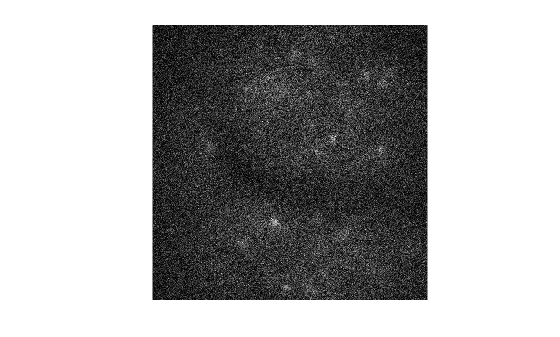

imshow(Reader.ReadPixels(7000,1,0,1,0,1),[]);

当你先后拍摄了多个OIR文件序列，希望串联成一个，可以使用此方法：

Image5D.OirReader.ConcatenateByRename(["\\Data-Server-2\双光子原始\张天夫\202402\yqn0153.202402240845.AuAuw.20%360V.oir"
"\\Data-Server-2\双光子原始\张天夫\202402\yqn0153.202402240845.AuAuw.20%360V_0001.oir"]);

如果串联的第一个文件有OIR索引，请务必记得删除索引文件，然后才能正确打开。此操作生成的串联序列不是OIR标准格式，只能用Image5D读入，FluoView和ImageJ可能无法读入。如果意外进行了错误的串联操作，可以在文件资源管理器空白处右键上下文菜单撤销。

如果上一步合并出错，也无法撤销，可以重新拆分。你需要构建一个拆分表，Index列出每个要拆出的子序列在原序列中的起始索引，HeaderName则列出子序列的文件名。

Index=86;
HeaderName="yqn2003.202301132231.LAWLwAw.13%430V23%460V";
Image5D.OirReader.SplitByRename("\\双光子主机\e\yqn\2023d7\yqn2003.202301131159.reference_0001.oir",table(Index,HeaderName));

# Ome Tiff 读写器

此测试用例基于bug创建

## 创建

import Image5D.*
OmeTiff=OmeTiffRWer.Create("E:\测试\测试.tif",PixelType.UINT16,512,512,ChannelColor.New(1,0,1,0),1,80000,DimensionOrder.XYCZT);

错误使用 Image5DMex
Image5D:Exception:File_creation_failed：系统找不到指定的路径。


出错 Image5D.internal.Image5DAPI/Call (第 59 行)
			[varargout{1:nargout}]=Image5DMex(uint64(obj),varargin{:});

出错 Image5D.OmeTiffRWer.Create (第 110 行)
					obj=OmeTiffRWer(internal.Image5DAPI.Tiff_Op

OmeTiff.WritePixels(randi(65535,512,512,'uint16'),70000,1);
delete(OmeTiff);

## 查看

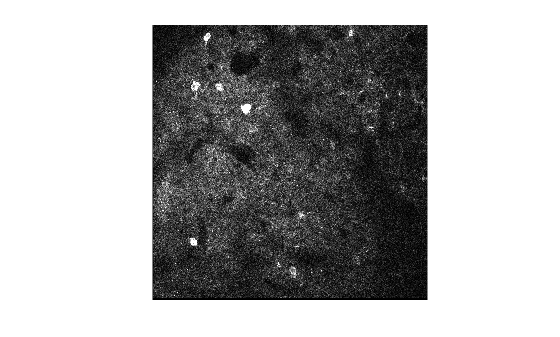

OmeTiff=Image5D.OmeTiffRWer.OpenRead("C:\Users\vhtmf\Desktop\Z1_Z1_deck2.tif");
imshow(OmeTiff.ReadPixelsI(6,1),[]);

## 修改

import Image5D.*
OmeTiff=OmeTiffRWer.OpenRW("C:\Users\vhtmf\Videos\测试\vtf0101.平均值.tif");

读出数据

imshow(OmeTiff.ReadPixels(0,1,1,1,0,1),[]);

修改颜色

OmeTiff.ChannelColors.G=0;

读出数据

imshow(OmeTiff.ReadPixels(0,1,1,1,0,1),[]);

## Big-endian

Reader=Image5D.OmeTiffRWer.OpenRead("\\计算服务器\Users\张天夫\Pictures\yqn2005.标准差.标准差.tif");

Pixels=Reader.ReadPixels;

imshow(Pixels(:,:,11),[]);